clear;
M = zeros(2, 4);
M(1, :) = [20 30 40 50];
M(2, :) = [8 23 28 34];
M

M =     20    30    40    50
     8    23    28    34


y = M(2, :);
humid = M(1, :);
elec = M(2, :);
x = (M(1, :) - 35) / 5

x =     -3    -1     1     3



A = zeros(2, length(x))

A =      0     0     0     0
     0     0     0     0


A(1, :) =  A(1, :) + 1

A =      1     1     1     1
     0     0     0     0


A(2, :) = x

A =      1     1     1     1
    -3    -1     1     3


A = A'

A =      1    -3
     1    -1
     1     1
     1     3



y = M(2, :)'

y =      8
    23
    28
    34


%u = [A b]';
A_star = A' * A

A_star =      4     0
     0    20


u_star = A' * y

u_star =     93
    83



u = mldivide(A_star, u_star);
u = u'

u =    23.2500    4.1500



lin_fit = u(1).*x + u(2)

lin_fit =   -65.6000  -19.1000   27.4000   73.9000


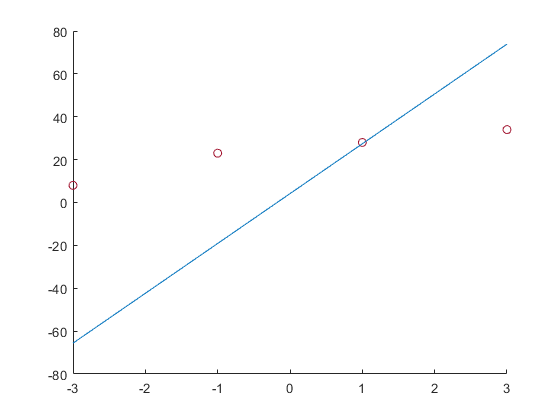

scatter(x, y);
hold on;
plot(x, lin_fit);